% 2019 
 %this takes a while, so just do it
% once and then save the data file and reload that later 
load LAdata.mat 

%don't have to do this every time, just load LAdata.mat file (better to not run)
%filename = ['hourly_SPEC_2010.csv','hourly_SPEC_2011.csv','hourly_SPEC_2012.csv','hourly_SPEC_2013.csv','hourly_SPEC_2014.csv'];
readtable('hourly_SPEC_2010.csv')
data = {};
data.countycode = table2array(ans(:,2));

Unrecognized function or variable 'ans'.

data.lat = table2array(ans(:,6));
data.lon = table2array(ans(:,7));
data.dategmt = table2array(ans(:,12));
data.timegmt = table2array(ans(:,13));
data.measurement = table2array(ans(:,14)); %'Micrograms/cubic meter (LC)'
data.state = table2array(ans(:,22));
data.county = table2array(ans(:,23));
data.site = table2array(ans(:,3));
%data is too big to save, have to index LA first and then save LAdata 

%indexing just LA data 
LAdata{1} = {}; 
LAdata{1}.index = (data.countycode == 73); 
LAdata{1}.lat = data.lat(LAdata.index);
LAdata{1}.lon = data.lon(LAdata.index);
LAdata{1}.dategmt = data.dategmt(LAdata.index);
LAdata{1}.timegmt = data.timegmt(LAdata.index);
LAdata{1}.measurement = data.measurement(LAdata.index);
LAdata{1}.site = data.site(LAdata.index);
save('LAdata'); 


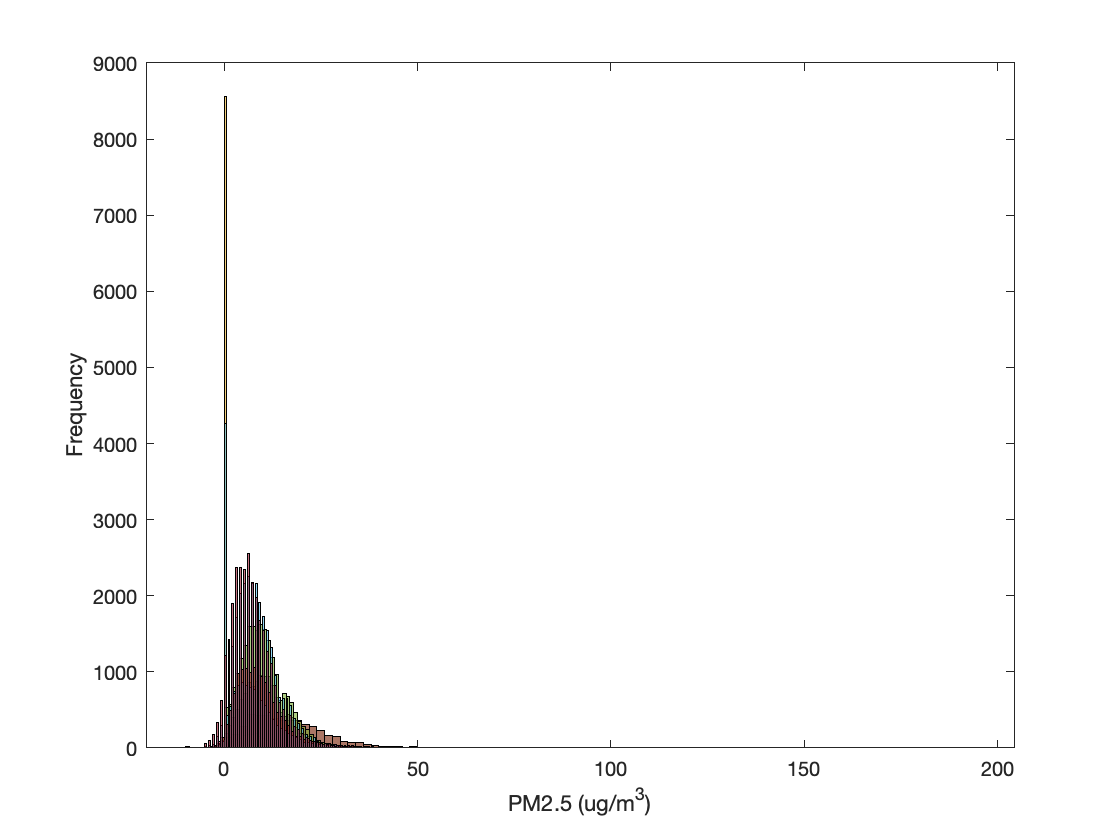


figure; clf
for i = 1:7 
    histogram(LAdata{i}.measurement);
    hold on
end 
ylabel('Frequency')
xlabel('PM2.5 (ug/m^3)')